%Tests the chance of a subtructure on a random number generator.
%Does the number of points (resolution) affect the presence of a substructure?
cadence = 0.03; %ms
duration = 30; %s
numberOfDataPoints = duration/cadence;

data = rand(1,numberOfDataPoints);
data = [10,data]

data =    10.0000    0.8905    0.8769    0.4110    0.0656    0.8473    0.2361    0.0566    0.8410    0.0966    0.1831    0.0640    0.5628    0.8773    0.3052    0.6523    0.2235    0.0350    0.6443    0.5395    0.9961    0.4192    0.9510    0.9927    0.1991    0.8703    0.6982    0.2255    0.6001    0.0192    0.7132    0.5234    0.7312    0.5314    0.8662    0.3066    0.0056    0.1887    0.9111    0.8953    0.8403    0.2578    0.2087    0.3482    0.4314    0.5975    0.3774    0.9653    0.3247    0.5780


meanData = mean(data);
sigma = std(data);

%Plot
timeVector = [0:cadence:duration];
meanVector = ones(1,length(timeVector)).*meanData

meanVector =     0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011    0.5011


sigmaVector = ones(1,length(timeVector)).*sigma

sigmaVector =     0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203    0.4203


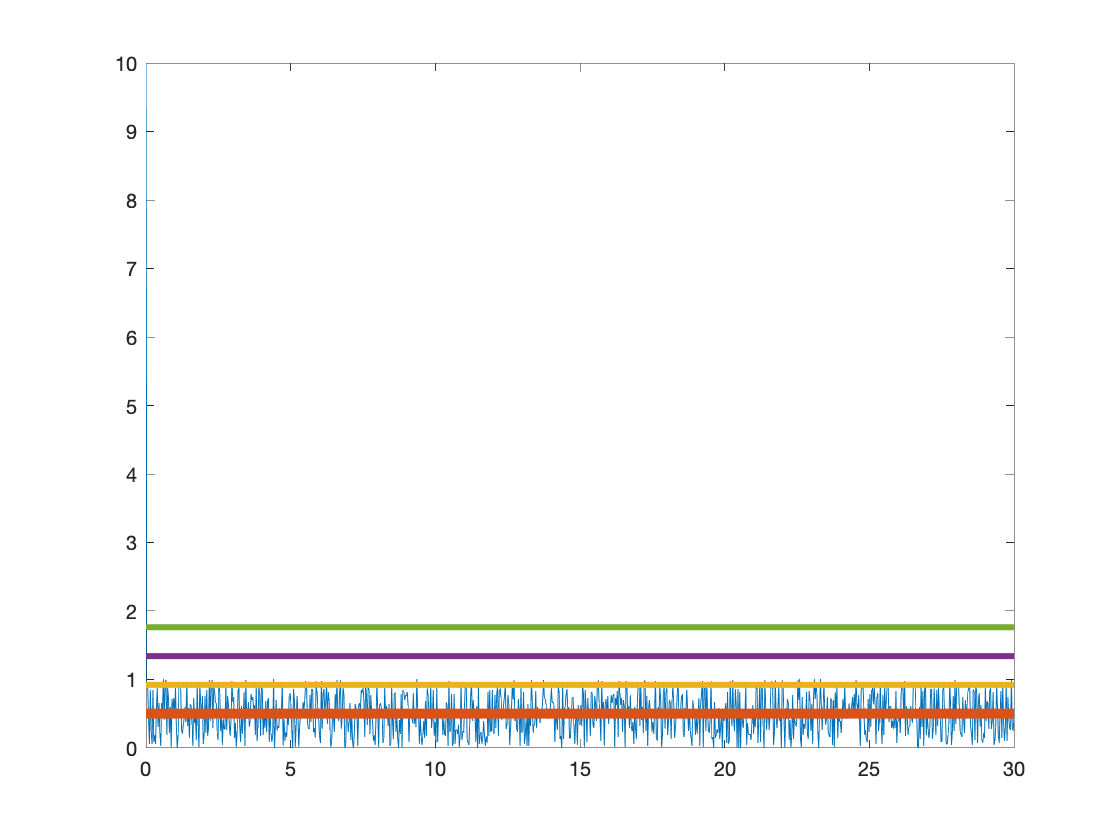

figure
plot([0:cadence:duration],[data]); hold on;
plot([0:cadence:duration],meanVector,'LineWidth',5)
plot([0:cadence:duration],meanVector+sigmaVector,'LineWidth',3)
plot([0:cadence:duration],meanVector+2*sigmaVector,'LineWidth',3)
plot([0:cadence:duration],meanVector+3*sigmaVector,'LineWidth',3)